clear

params;

dt = 0.01;

% Simulation
tic
% Initialize variables
prev_error = 0;
integral = 0;
prev_t = 0;
z0 = z_eq + 0.03; % Initial condition
% Pre-allocate arrays to store results
tf = 10.0;
tSpan = linspace(0,tf,tf/dt); % Time vector of tf seconds (100Hz)
z_ref = z_eq + 0.02;
dz_ref = 0;
num_steps = tf * 100;
t_result = zeros(num_steps, 1);
x_result = zeros(num_steps, 2);
u_signal = zeros(num_steps, 1);
error_sig = zeros(num_steps, 1);

% Control loop
t_current = 0.0;
x_current = zeros(2,1);
x_current(1) = z0;
for i = 1:num_steps
    % Calculate error
    error = z_ref - x_current(1);
    error_sig(i) = error;
    
    % Calculate control signal
    u = 0;
    u_signal(i) = u;

    % Store current time and state
    t_result(i) = t_current;
    x_result(i, :) = x_current;
    
    % Update state using ode integration
    [t_out, x_out] = ode15s(@(t, x) f_sim(x, u), [t_current t_current + dt], x_current);
    
    % Update current time and state for next iteration
    prev_error = error;
    prev_t = t_current;
    t_current = t_out(end);
    x_current = x_out(end, :);
end


fprintf('simulation time: %.2fs\n', toc)

simulation time: 0.46s


### Plotting results

We plot the position of the center of the magnet to see the results of the simulation.

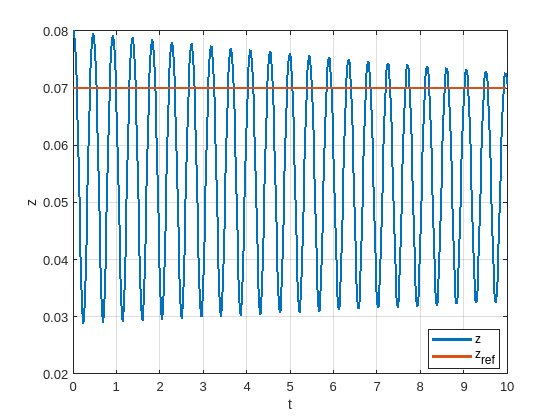

figure;
clf; grid on; hold on; box on;

plot(t_result, x_result(:, 1),'linewidth',2)
plot(t_result, z_ref * ones(num_steps,1),'linewidth',2)
legend({'z','z_{ref}'},'location','best')
xlabel('t')
ylabel('z')

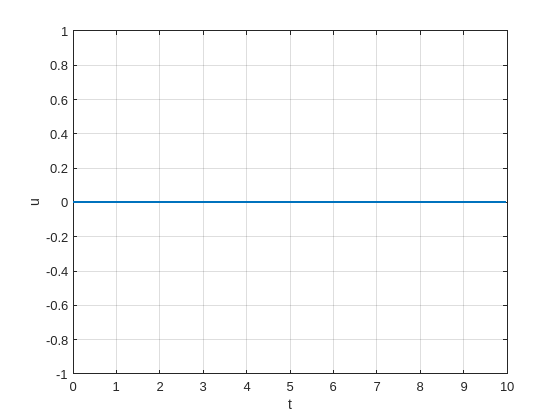


figure
clf; grid on; hold on; box on;

plot(t_result, u_signal,'linewidth',2)
xlabel('t')
ylabel('u')

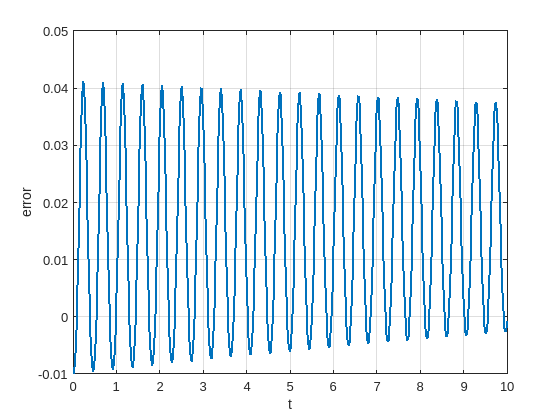

figure
clf; grid on; hold on; box on;

plot(t_result, error_sig,'linewidth',2)
ylabel('error')
xlabel('t')